# Ex05. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Examing FFT and DFTS in MATLAB

This assignment involves calculating and plotting eight functions transformed using the Fast Fourier Transform (FFT), Discrete Fourier Series (DFS/DTFS), and Discrete-Time Fourier Transform (DTFT). For the numerical computation, the discrete time index n ranges from 0 to 255 with an increment of 1. The frequency domain ω is sampled at intervals of 0.0001 (from 0 to 2*pi), and the constant a is set to 0.6. The resulting waveforms are organized into a 4 * 2 subplot grid for comparative analysis.

#### 1.1. MATLAB Code

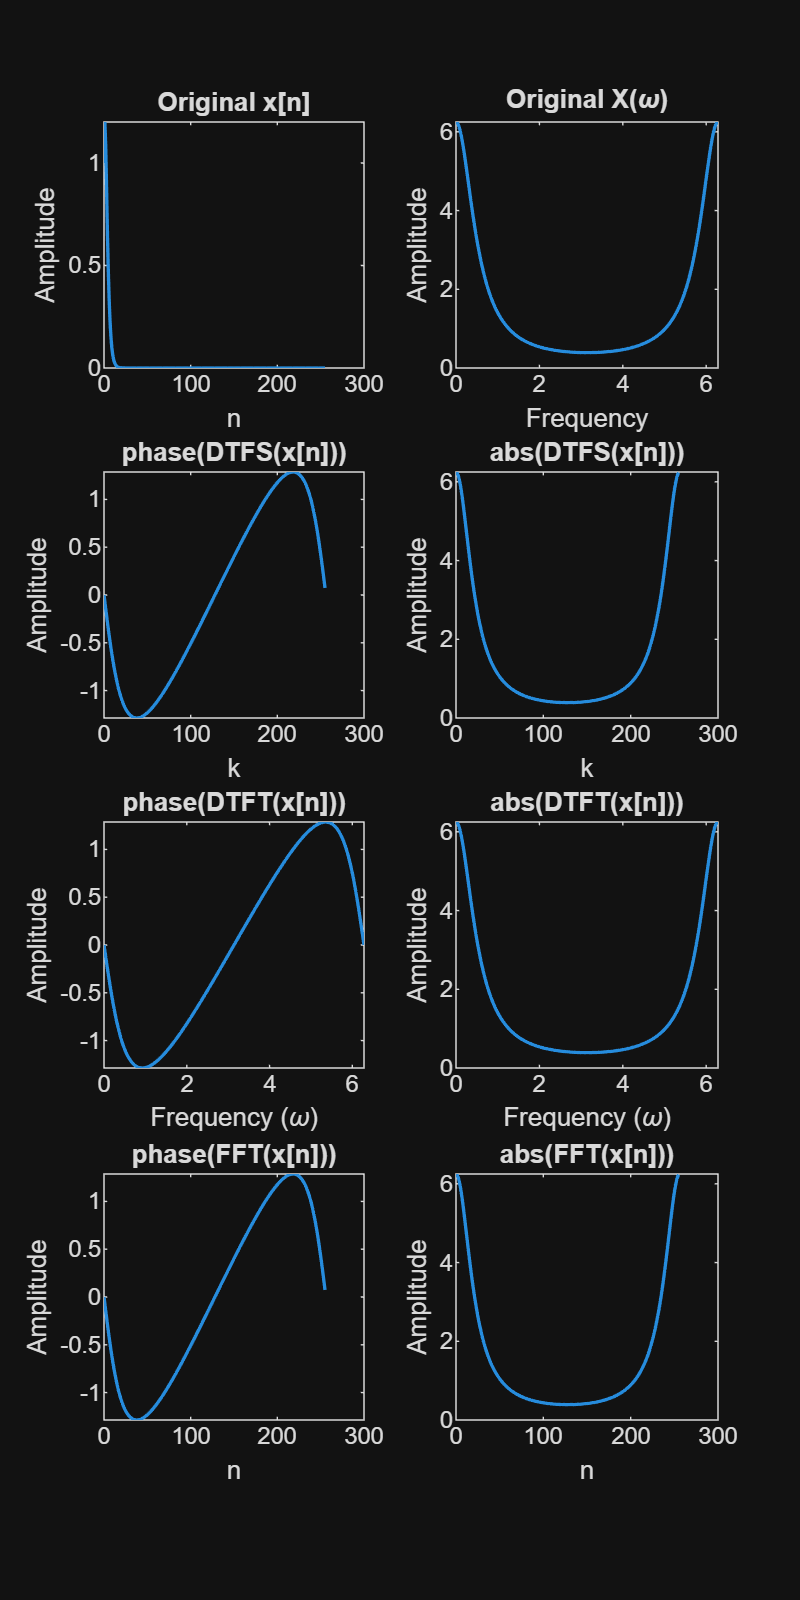

n = 0:1:255;
omega = 0:0.0001:2*pi;
a = 0.6;
X = @(omega) 1 ./((1 - a .* exp(-1j .* omega)).^2);
x = @(n) (a.^n) .* (n+1) .* (n >= 0);

figure('Position', [100, 100, 500, 1000]);

columnLabels = {'DTFS', 'DTFT', 'FFT'};
rowLabels = {'phase', 'abs'};
dataMatrix = zeros([2, 3]);

subplot(4, 2, 1);
p1 = plot(n, x(n),'LineWidth', 1.2); 
xlabel("n");
ylabel("Amplitude");
title('Original x[n]');

subplot(4, 2, 2);
p2 = plot(omega, abs(X(omega)),'LineWidth', 1.2); 
xlabel("Frequency");
ylabel("Amplitude");
title('Original X(\omega)');

%---Caluclating DTFS---
tic;
sum_DTFS = zeros(1, 256);
for k = 1:256
  sum_DTFS(k) = sum(x(n) .* exp(-1j * (2*pi/256) * (k-1) .* n)); 
end
func3 = phase(sum_DTFS);
dataMatrix(1, 1) = toc;

subplot(4, 2, 3);
p3 = plot(n, func3, 'LineWidth', 1.2);
xlabel("k");
ylabel("Amplitude");
title('phase(DTFS(x[n]))');

tic;
sum_DTFS = zeros(1, 256);
for k = 1:256
  sum_DTFS(k) = sum(x(n) .* exp(-1j * (2*pi/256) * (k-1) .* n)); 
end
func4 = abs(sum_DTFS);
dataMatrix(2, 1) = toc;

subplot(4, 2, 4);
p4 = plot(n, func4, 'LineWidth', 1.2);
xlabel("k");
ylabel("Amplitude");
title('abs(DTFS(x[n]))');

%---Caluclating DTFT---
tic;
sum_DTFT = 0;
for i = n
sum_DTFT =  sum_DTFT + x(i) .* exp(-1j .* omega  .* i );
end
func5 = phase(sum_DTFT);
dataMatrix(1, 2) = toc;

subplot(4, 2, 5);
p5 = plot(omega, func5, 'LineWidth', 1.2);
xlabel("Frequency (\omega)");
ylabel("Amplitude");
title('phase(DTFT(x[n]))');

tic;
sum_DTFT = 0;
for i = n
sum_DTFT =  sum_DTFT + x(i) .* exp(-1j .* omega  .* i );
end
func6 = abs(sum_DTFT);
dataMatrix(2, 2) = toc;

subplot(4, 2, 6);
p6 = plot(omega, func6, 'LineWidth', 1.2);
xlabel("Frequency (\omega)");
ylabel("Amplitude");
title('abs(DTFT(x[n]))');

%---Caluclating DFT---
tic;
func7 = phase(fft(x(n)));
dataMatrix(1, 3) = toc;

subplot(4, 2, 7);
p7 = plot(n, func7,'LineWidth', 1.2);
xlabel("n");
ylabel("Amplitude");
title('phase(FFT(x[n]))');

tic;
func8 = abs(fft(x(n)));
dataMatrix(2, 3) = toc;

subplot(4, 2, 8);
p8 = plot(n, func8,'LineWidth', 1.2); 
xlabel("n");
ylabel("Amplitude");
title('abs(FFT(x[n]))');


T = array2table(dataMatrix, 'RowNames', rowLabels, 'VariableNames', columnLabels);
disp(T);

               DTFS        DTFT        FFT   
             ________    ________    ________

    phase    0.013321    0.091651    0.001404
    abs      0.013354    0.078784    0.001487



#### 1.2. Discussion

 The computational times for the various Fourier Transform options (such as DTFS, DTFT, and FFT) showed a consistent trend. The DTFT took by far the longest time to compute, at approximately 0.09s and 0.07s. The second longest times were recorded for the phase and absolute values of the DTFS, at about 0.0133s. In contrast, the fastest method was the FFT (Fast Fourier Transform), with a computational time roughly one-tenth that of the DTFS.

Based on these results, I would like to analyze the factors that contributed to this outcome. The 256-iteration loop and the frequency array ω led to the extensive computation time in the DTFT. Since the array ω contains approximately 6.28 * 10^4 elements, the CPU must perform over 6.28 * 10^4 * 256 = 16,076,800 operations within the for-loop. On the other hand, for the DTFS, the CPU only needs to compute about 256 * 256 = 65,536 values, which is significantly fewer than the DTFT. Despite producing similar output graphs, there is a substantial difference in execution time between the DTFS and the FFT. This can be attributed to the time complexity of each algorithm. While the DTFS has a time complexity of O(N^2), that of the FFT is O(N \log_2 N). Thus, the superior computational efficiency of the FFT has been clearly demonstrated.

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem.